%% AI Clinician core code

% version 16 Feb 19
% Builds 100 models using MIMIC-III training data
% Records best candidate models along the way from off-policy policy evaluation on MIMIC-III validation data

% TAKES:
        % MIMICtable = m*59 table with raw values from MIMIC

% GENERATES:
        % MIMICraw = MIMIC RAW DATA m*47 array with columns in right order
        % MIMICzs = MIMIC ZSCORED m*47 array with columns in right order, matching MIMICraw
        % recqvi = summary statistics of all 100 models
        % idxs = state membership of MIMIC test records, for all 100 models
     	% OA = optimal policy, for all 100 models
        % allpols = detailed data about the best candidate models

%% ###### Read MIMIC table from csv file
MIMICtable = readtable('mimiciii_dataset.csv','Delimiter',',','ReadVariableNames',true);

% Add MDP toolbox to MATLAB Path
addpath('C:\Users\amrut\Projects\AI_Clinician\MDPtoolbox','-end')

% ############################  MODEL PARAMETERS   #####################################

disp('####  INITIALISATION  ####') 

####  INITIALISATION  ####



nr_reps=10;%500;               % nr of repetitions (total nr models)
nclustering=32;            % how many times we do clustering (best solution will be chosen)
prop=0.25;                 % proportion of the data we sample for clustering
gamma=0.99;                % gamma
transthres=5;              % threshold for pruning the transition matrix
polkeep=1;                 % count of saved policies
ncl=750;                   % nr of states
nra=5;                     % nr of actions (2 to 10)
ncv=5;                     % nr of crossvalidation runs (each is 80% training / 20% test)
OA=NaN(752,nr_reps);       % record of optimal actions
recqvi=NaN(nr_reps*2,30);  % saves data about each model (1 row per model)
allpols=cell(nr_reps,15);  % saving best candidate models


% #################   Convert training data and compute conversion factors    ######################
tic;

% all 47 columns of interest
colbin = {'gender','mechvent','max_dose_vaso','re_admission'};
colnorm={'age','Weight_kg','GCS','HR','SysBP','MeanBP','DiaBP','RR','Temp_C','FiO2_1',...
    'Potassium','Sodium','Chloride','Glucose','Magnesium','Calcium',...
    'Hb','WBC_count','Platelets_count','PTT','PT','Arterial_pH','paO2','paCO2',...
    'Arterial_BE','HCO3','Arterial_lactate','SOFA','SIRS','Shock_Index','PaO2_FiO2','cumulated_balance'};
collog={'SpO2','BUN','Creatinine','SGOT','SGPT','Total_bili','INR','input_total','input_4hourly','output_total','output_4hourly'};

colbin=find(ismember(MIMICtable.Properties.VariableNames,colbin));colnorm=find(ismember(MIMICtable.Properties.VariableNames,colnorm));collog=find(ismember(MIMICtable.Properties.VariableNames,collog));

% find patients who died in ICU during data collection period
% ii=MIMICtable.bloc==1&MIMICtable.died_within_48h_of_out_time==1& MIMICtable.delay_end_of_record_and_discharge_or_death<24;
% icustayidlist=MIMICtable.icustayid;
% ikeep=~ismember(icustayidlist,MIMICtable.icustayid(ii));
reformat5=table2array(MIMICtable);
% reformat5=reformat5(ikeep,:);
icustayidlist=MIMICtable.icustayid;
icuuniqueids=unique(icustayidlist); %list of unique icustayids from MIMIC
idxs=NaN(size(icustayidlist,1),nr_reps); %record state membership test cohort


MIMICraw=MIMICtable(:, [colbin colnorm collog]);
MIMICraw=table2array(MIMICraw);  % RAW values


%% Split data into train set (MIMICraw) and test set (eICUraw - XTest)
N=numel(icuuniqueids); %total number of rows to choose from
grp=floor(5*rand(N,1)+1);  %list of 1 to 5 (20% of the data in each grp) -- train/test MIMIC split- 80%/20%
testset=1;
trainidx=icuuniqueids(testset~=grp);
xtestidx=icuuniqueids(testset==grp);
train=ismember(icustayidlist,trainidx);
xtest=ismember(icustayidlist,xtestidx);

eICUtable=MIMICtable(~train, :);

temp=MIMICraw(train,:);
eICUraw=MIMICraw(~train,:);
MIMICraw=temp;
%%


MIMICzs=[reformat5(:, colbin)-0.5 zscore(reformat5(:,colnorm)) zscore(log(0.1+reformat5(:, collog)))];  
MIMICzs(:,[4])=log(MIMICzs(:,[ 4])+.6);   % MAX DOSE NORAD 
MIMICzs(:,45)=2.*MIMICzs(:,45);   % increase weight of this variable

    
% compute conversion factors using MIMIC data
a=MIMICraw(:, 1:3)-0.5; 
[b]= log(MIMICraw(:, 4)+0.1);
[c,cmu,csigma]=zscore(MIMICraw(:,5:36));
[d,dmu,dsigma]=zscore(log(0.1+MIMICraw(:,37:47)));


% ZSCORE full at once XTEST using the factors from training data
eICUzs=eICUraw;
eICUzs(:,1:3)=eICUzs(:,1:3)-0.5;
eICUzs(:,4)=log(eICUzs(:,4)+0.1);
eICUzs(:,5:36)=(eICUzs(:,5:36)-cmu)./csigma;
eICUzs(:,37:47)=(log(0.1+eICUzs(:,37:47))-dmu)./dsigma;

if sum(isnan(eICUraw(:,4))) >0 || sum(isnan(eICUraw(:,45)))>0;  disp('NaNs in eICUraw (XTEST) / drug doses'); disp('EXECUTION STOPPED'); return;end

toc

Elapsed time is 1.841483 seconds.


p=gcp('nocreate'); if isempty(p) ; pool = parpool; end ; mdp_verbose

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


stream = RandStream('mlfg6331_64'); options = statset('UseParallel',1,'UseSubstreams',1,'Streams',stream); warning('off','all')

for modl=1:nr_reps  % MAIN LOOP OVER ALL MODELS
   
      N=numel(icuuniqueids); %total number of rows to choose from
      grp=floor(ncv*rand(N,1)+1);  %list of 1 to 5 (20% of the data in each grp) -- this means that train/test MIMIC split are DIFFERENT in all the 500 models
      crossval=1;
      trainidx=icuuniqueids(crossval~=grp);
      testidx=icuuniqueids(crossval==grp);
      train=ismember(icustayidlist,trainidx);
      test=ismember(icustayidlist,testidx);
      X=MIMICzs(train,:);
      Xtestmimic=MIMICzs(~train,:);
      blocs=reformat5(train,1);
      bloctestmimic=reformat5(~train,1);
      ptid=reformat5(train,2);
      ptidtestmimic=reformat5(~train,2);
      outcome=10; %   HOSP _ MORTALITY = 8 / 90d MORTA = 10
      Y90=reformat5(train,outcome);   

    fprintf('########################   MODEL NUMBER : ');       fprintf('%d \n',modl);         disp( datestr(now))
          
 
    % #######   find best clustering solution (lowest intracluster variability)  ####################
    disp('####  CLUSTERING  ####') % BY SAMPLING
    N=size(X,1); %total number of rows to choose from
    sampl=X(find(floor(rand(N,1)+prop)),:);
    [~,C] = kmeans(sampl,ncl,'Options',options,'MaxIter',10000,...
        'Start','plus','Display','final','Replicates',nclustering);
    [idx]=knnsearch(C,X);  %N-D nearest point search: look for points closest to each centroid


    %  ############################# CREATE ACTIONS  ########################
    disp('####  CREATE ACTIONS  ####') 
    nact=nra^2;
 
    iol=find(ismember(MIMICtable.Properties.VariableNames,{'input_4hourly'}));
    vcl=find(ismember(MIMICtable.Properties.VariableNames,{'max_dose_vaso'}));

     a= reformat5(:,iol);                   %IV fluid
     a= tiedrank(a(a>0)) / length(a(a>0));   % excludes zero fluid (will be action 1)

            iof=floor((a+0.2499999999)*4);  %converts iv volume in 4 actions
            a= reformat5(:,iol); a=find(a>0);  %location of non-zero fluid in big matrix
            io=ones(size(reformat5,1),1);  %array of ones, by default     
            io(a)=iof+1;   %where more than zero fluid given: save actual action
            vc=reformat5(:,vcl);  vcr= tiedrank(vc(vc~=0)) / numel(vc(vc~=0)); vcr=floor((vcr+0.249999999999)*4);  %converts to 4 bins
            vcr(vcr==0)=1; vc(vc~=0)=vcr+1; vc(vc==0)=1;
            ma1=[ median(reformat5(io==1,iol))  median(reformat5(io==2,iol))  median(reformat5(io==3,iol))  median(reformat5(io==4,iol))  median(reformat5(io==5,iol))];  %median dose of drug in all bins
            ma2=[ median(reformat5(vc==1,vcl))  median(reformat5(vc==2,vcl))  median(reformat5(vc==3,vcl))  median(reformat5(vc==4,vcl))  median(reformat5(vc==5,vcl))] ;

    med=[io vc];
    [uniqueValues,~,actionbloc] = unique(array2table(med),'rows');
    actionbloctrain=actionbloc(train);
    uniqueValuesdose=[ ma2(uniqueValues.med2)' ma1(uniqueValues.med1)'];  % median dose of each bin for all 25 actions

 
    % ###################################################################################################################################
    disp('####  CREATE QLDATA3  ####')
    r=[100 -100]; r2=r.*(2*(1-Y90)-1); 
    qldata=[blocs idx actionbloctrain Y90 r2];  % contains bloc / state / action / outcome&reward     %1 = died
    qldata3=zeros(floor(size(qldata,1)*1.2),4); 
    c=0;
    abss=[ncl+2 ncl+1]; %absorbing states numbers
 
        for i=1:size(qldata,1)-1
            c=c+1;  qldata3(c,:)=qldata(i,1:4);
            if qldata(i+1,1)==1 %end of trace for this patient
                c=c+1;     qldata3(c,:)=[qldata(i,1)+1 abss(1+qldata(i,4)) 0 qldata(i,5)]; 
            end
        end
        qldata3(c+1:end,:)=[];

 
    % ###################################################################################################################################
    disp('####  CREATE TRANSITION MATRIX T(S'',S,A) ####')

    transitionr=zeros(ncl+2,ncl+2,nact);  %this is T(S',S,A)
    sums0a0=zeros(ncl+2,nact);

         for i=1:size(qldata3,1)-1

             if (qldata3(i+1,1))~=1  % if we are not in the last state for this patient = if there is a transition to make!
             S0=qldata3(i,2); S1=qldata3(i+1,2);  acid= qldata3(i,3);
             transitionr(S1,S0,acid)=transitionr(S1,S0,acid)+1;  sums0a0(S0,acid)=sums0a0(S0,acid)+1;
             end
         end

          sums0a0(sums0a0<=transthres)=0;  %delete rare transitions (those seen less than 5 times = bottom 50%!!)

         for i=1:ncl+2
             for j=1:nact
                 if sums0a0(i,j)==0
                    transitionr(:,i,j)=0; 
                 else
                    transitionr(:,i,j)=transitionr(:,i,j)/sums0a0(i,j);
                 end
             end
         end

   
    transitionr(isnan(transitionr))=0;  %replace NANs with zeros
    transitionr(isinf(transitionr))=0;  %replace NANs with zeros

    physpol=sums0a0./sum(sums0a0')';    %physicians policy: what action was chosen in each state

    % transitionr(i,j,k) == transitionr2(j,i,k)

     disp('####  CREATE TRANSITION MATRIX T(S,S'',A)  ####')

    transitionr2=zeros(ncl+2,ncl+2,nact);  % this is T(S,S',A)
    sums0a0=zeros(ncl+2,nact);

         for i=1:size(qldata3,1)-1

             if (qldata3(i+1,1))~=1  % if we are not in the last state for this patient = if there is a transition to make!
             S0=qldata3(i,2); S1=qldata3(i+1,2);  acid= qldata3(i,3);
             transitionr2(S0,S1,acid)=transitionr2(S0,S1,acid)+1;  sums0a0(S0,acid)=sums0a0(S0,acid)+1;
             end
         end

        sums0a0(sums0a0<=transthres)=0;  %delete rare transitions (those seen less than 5 times = bottom 50%!!) IQR = 2-17
     
         for i=1:ncl+2
             for j=1:nact
                 if sums0a0(i,j)==0
                    transitionr2(i,:,j)=0; 
                 else
                    transitionr2(i,:,j)=transitionr2(i,:,j)/sums0a0(i,j);
                 end
             end
         end

    transitionr2(isnan(transitionr2))=0;  %replace NANs with zeros
    transitionr2(isinf(transitionr2))=0;  %replace infs with zeros
 
    % #################################################################################################################################
    disp('####  CREATE REWARD MATRIX  R(S,A) ####')
    % CF sutton& barto bottom 1998 page 106. i compute R(S,A) from R(S'SA) and T(S'SA)
    r3=zeros(ncl+2,ncl+2,nact); r3(ncl+1,:,:)=-100; r3(ncl+2,:,:)=100;
    R=sum(transitionr.*r3);
    R=squeeze(R);   %remove 1 unused dimension

    % ###################################################################################################################################
    disp('####   POLICY ITERATION   ####')

     [~,~,~,~,Qon] = mdp_policy_iteration_with_Q(transitionr2, R, gamma, ones(ncl+2,1));
     [~,OptimalAction]=max(Qon,[],2);  %deterministic 
     OA(:,modl)=OptimalAction; %save optimal actions
 
    disp('#### OFF-POLICY EVALUATION - MIMIC TRAIN SET ####')

    % create new version of QLDATA3
    r=[100 -100];
    r2=r.*(2*(1-Y90)-1); 
    qldata=[blocs idx actionbloctrain Y90 zeros(numel(idx),1) r2(:,1) ptid];  % contains bloc / state / action / outcome&reward     %1 = died
    qldata3=zeros(floor(size(qldata,1)*1.2),8); 

    c=0;
    abss=[ncl+2 ncl+1]; %absorbing states numbers
 
        for i=1:size(qldata,1)-1
            c=c+1;
              qldata3(c,:)=qldata(i,[1:3 5 7 7 7 7]);
            if qldata(i+1,1)==1 %end of trace for this patient
                c=c+1;
                qldata3(c,:)=[qldata(i,1)+1 abss(1+qldata(i,4)) 0 qldata(i,6) 0 0 0 qldata(i,7)]; 
            end
        end
        qldata3(c+1:end,:)=[];

    % add pi(s,a) and b(s,a)
    p=0.01; %softening policies  
    softpi=physpol; % behavior policy = clinicians' 

    for i=1:750
        ii=softpi(i,:)==0;    z=p/sum(ii);    nz=p/sum(~ii);    softpi(i,ii)=z;   softpi(i,~ii)=softpi(i,~ii)-nz;
    end
    softb=abs(zeros(752,25)-p/24); %"optimal" policy = target policy = evaluation policy 

    for i=1:750
         softb(i,OptimalAction(i))=1-p;
    end

    for i=1:size(qldata3,1)  %adding the probas of policies to qldata3
        if qldata3(i,2)<=750
    qldata3(i,5)=softpi(qldata3(i,2),qldata3(i,3));
    qldata3(i,6)=softb(qldata3(i,2),qldata3(i,3));
    qldata3(i,7)=OptimalAction(qldata3(i,2));   %optimal action
        end
    end

    qldata3train=qldata3;

    tic
     [ bootql,bootwis ] = offpolicy_multiple_eval_010518( qldata3,physpol, 0.99,1,6,750);
    toc

    recqvi(modl,1)=modl;
    recqvi(modl,4)=nanmean(bootql);
    recqvi(modl,5)=quantile(bootql,0.99);
    recqvi(modl,6)=nanmean(bootwis);  %we want this as high as possible
    recqvi(modl,7)=quantile(bootwis,0.05);  %we want this as high as possible


    % testing on MIMIC-test
    disp('#### OFF-POLICY EVALUATION - MIMIC TEST SET ####')

    % create new version of QLDATA3 with MIMIC TEST samples
    idxtest=knnsearch(C,Xtestmimic);
    idxs(test,modl)=idxtest;  %important: record state membership of test cohort

    actionbloctest=actionbloc(~train);
    Y90test=reformat5(~train,outcome);
    r=[100 -100];
    r2=r.*(2*(1-Y90test)-1); 
    qldata=[bloctestmimic idxtest actionbloctest Y90test zeros(numel(idxtest),1) r2(:,1) ptidtestmimic];  % contains bloc / state / action / outcome&reward     %1 = died
    qldata3=zeros(floor(size(qldata,1)*1.2),8); 

    c=0;
    abss=[ncl+2 ncl+1]; %absorbing states numbers
 
        for i=1:size(qldata,1)-1
            c=c+1; qldata3(c,:)=qldata(i,[1:3 5 7 7 7 7]);
            if qldata(i+1,1)==1 %end of trace for this patient
                c=c+1; qldata3(c,:)=[qldata(i,1)+1 abss(1+qldata(i,4)) 0 qldata(i,6) 0 0 0 qldata(i,7)]; 
            end
        end
        qldata3(c+1:end,:)=[];

    % add pi(s,a) and b(s,a)
    p=0.01; %small correction factor // softening policies
    softpi=physpol; % behavior policy = clinicians'
    for i=1:750 
        ii=softpi(i,:)==0;    z=p/sum(ii);    nz=p/sum(~ii);    softpi(i,ii)=z;   softpi(i,~ii)=softpi(i,~ii)-nz;
    end
    
    softb=abs(zeros(752,25)-p/24); %"optimal" policy = target policy = evaluation policy
    
    for i=1:750
        softb(i,OptimalAction(i))=1-p;
    end

    
    for i=1:size(qldata3,1)  %adding the probas of policies to qldata
        if qldata3(i,2)<=750
    qldata3(i,5)=softpi(qldata3(i,2),qldata3(i,3));
    qldata3(i,6)=softb(qldata3(i,2),qldata3(i,3));
    qldata3(i,7)=OptimalAction(qldata3(i,2));   %optimal action
        end
    end

    qldata3test=qldata3;

    tic
    [ bootmimictestql,bootmimictestwis ] = offpolicy_multiple_eval_010518( qldata3,physpol, 0.99,1,6,2000);
    toc

    recqvi(modl,19)=quantile(bootmimictestql,0.95);   %PHYSICIANS' 95% UB
    recqvi(modl,20)=nanmean(bootmimictestql);
    recqvi(modl,21)=quantile(bootmimictestql,0.99);
    recqvi(modl,22)=nanmean(bootmimictestwis);    
    recqvi(modl,23)=quantile(bootmimictestwis,0.01);  
    recqvi(modl,24)=quantile(bootmimictestwis,0.05);  %AI 95% LB, we want this as high as possible


    if recqvi(modl,24) > 40 %saves time if policy is not good on MIMIC test: skips to next model

        disp('########################## eICU TEST SET #############################')
        
          idxtest2=cell(size(eICUzs,1),1);
                ii=isnan(eICUzs);
                disp('####   IDENTIFY STATE MEMBERSHIP OF eICU TEST RECORDS   ####')
            tic
              parfor i=1:size(eICUzs,1)
                idxtest2(i)={knnsearch(C(:,~ii(i,:)),eICUzs(i,~ii(i,:)))};  %which ones are the k closest records in Xtrain? - only match on available data (ii columns)!
              end
            toc
            
          idxtest2=cell2mat(idxtest2);
        
        iol=find(ismember(MIMICtable.Properties.VariableNames,{'input_4hourly'}));
        vcl=find(ismember(MIMICtable.Properties.VariableNames,{'max_dose_vaso'}));
         
         a= reformat5(:,iol);                    %IV fluid
         a= tiedrank(a(a>0)) / length(a(a>0));   % excludes zero fluid (will be action 1)
         
                iof=floor((a+0.2499999999)*4);       %converts iv volume in 4 actions
                a= reformat5(:,iol); a=find(a>0);    %location of non-zero fluid in big matrix
                io=ones(size(reformat5,1),1);        %array of ones, by default     
                io(a)=iof+1;                         %where more than zero fluid given: save actual action
                vc=reformat5(:,vcl);  vcr= tiedrank(vc(vc~=0)) / numel(vc(vc~=0)); vcr=floor((vcr+0.249999999999)*4);  %converts to 4 bins
                vcr(vcr==0)=1; vc(vc~=0)=vcr+1; vc(vc==0)=1;
                ma1=[ median(reformat5(io==1,iol))  median(reformat5(io==2,iol))  median(reformat5(io==3,iol))  median(reformat5(io==4,iol))  median(reformat5(io==5,iol))];  %median dose of drug in all bins
                ma2=[ median(reformat5(vc==1,vcl))  median(reformat5(vc==2,vcl))  median(reformat5(vc==3,vcl))  median(reformat5(vc==4,vcl))  median(reformat5(vc==5,vcl))] ;
          
        med=[io vc];
        [uniqueValues,~,actionbloc] = unique(array2table(med),'rows');
        actionbloctrain=actionbloc(train);
        uniqueValuesdose=[ ma2(uniqueValues.med2)' ma1(uniqueValues.med1)'];  % median dose of each bin for all 25 actions
         
        iol=find(ismember(MIMICtable.Properties.VariableNames,{'input_4hourly'}));
        vcl=find(ismember(MIMICtable.Properties.VariableNames,{'max_dose_vaso'}));
        ma1=[ max(reformat5(io==1,iol))  max(reformat5(io==2,iol))  max(reformat5(io==3,iol))  max(reformat5(io==4,iol))  max(reformat5(io==5,iol))];  %upper dose of drug in all bins
        ma2=[ max(reformat5(vc==1,vcl))  max(reformat5(vc==2,vcl))  max(reformat5(vc==3,vcl))  max(reformat5(vc==4,vcl))  max(reformat5(vc==5,vcl))] ;
        
        % define actionbloctest = which actions are taken in the test set ????
        vct=eICUraw(:,4); vct(vct>ma2(nra-1))=nra; vct(vct==0)=1; for z=2:nra-1; vct(vct>ma2(z-1) & vct<=ma2(z))=z;end
        iot=eICUraw(:,45); for z=2:nra-1; iot(iot>ma1(z-1) & iot<=ma1(z))=z; end;iot(iot>ma1(nra-1))=nra;iot(iot==0)=1;
         
        med=[iot vct];
        [~,~,actionbloctest] = unique(array2table(med),'rows');   %actions taken in my test samples
         
        iol=eICUraw(:,45);      % DOSES IN TEST SET
        vcl=eICUraw(:,4);
        
        % CREATE QLDATA2 FOR EICU TEST SET
        
        ptid=eICUtable.icustayid;
        blocstest=eICUtable.bloc;
        Y90test=eICUtable.mortality_90d;
        r=[100 -100];
        r2=r.*(2*(1-Y90test)-1); 
        models=OptimalAction(idxtest2);                  %optimal action for each record
        modeldosevaso = uniqueValuesdose(models,1);      %dose reco in this model
        modeldosefluid = uniqueValuesdose(models,2);     %dose reco in this model
        
        
        
        qldata=[blocstest idxtest2 actionbloctest Y90test zeros(numel(idxtest2),1) r2(:,1) ptid  iol vcl modeldosefluid modeldosevaso  Y90test ];  % contains bloc / state / action / outcome&reward     %1 = died
        qldata2=zeros(floor(size(qldata,1)*1.2),13); 
        c=0;
        abss=[ncl+2 ncl+1]; %absorbing states numbers
         
                for i=1:size(qldata,1)-1
                    c=c+1;
                      qldata2(c,:)=qldata(i,[1:3 5 7 7 7 7 8:12]);
                    if qldata(i+1,1)==1 %end of trace for this patient
                        c=c+1;
                        qldata2(c,:)=[qldata(i,1)+1 abss(1+qldata(i,4)) 0 qldata(i,6) 0 0 0 qldata(i,7) qldata(i,8:12)]; 
                    end
                end
        qldata2(c+1:end,:)=[];


        % add pi(s,a) and b(s,a)
        p=0.01; % softening policies

        softpi=physpol;%physpoleicu;   
        for i=1:750
            ii=softpi(i,:)==0; z=p/sum(ii); nz=p/sum(~ii); softpi(i,ii)=z; softpi(i,~ii)=softpi(i,~ii)-nz;
        end

        softb=abs(zeros(752,25)-p/24); %optimal policy
        for i=1:750
            softb(i,OptimalAction(i))=1-p;
        end

        for i=1:size(qldata2,1)  %adding the probas of policies to qldata
                if qldata2(i,2)<=750
            qldata2(i,5)=softpi(qldata2(i,2),qldata2(i,3));
            qldata2(i,6)=softb(qldata2(i,2),qldata2(i,3));
            qldata2(i,7)=OptimalAction(qldata2(i,2)); 
                end
        end

        tic  %multiple evaluation
         [ booteicuql,booteicuwis ] = offpolicy_multiple_eval_010518( qldata2,physpol, 0.99,1,20,500);
        toc

        recqvi(modl,10)=nanmean(booteicuql);
        recqvi(modl,11)=quantile(booteicuql,0.99);
        recqvi(modl,12)=nanmean(booteicuwis); 
        recqvi(modl,13)=quantile(booteicuwis,0.01);  
        recqvi(modl,14)=quantile(booteicuwis,0.05); 


    end


    if recqvi(modl,24)>0 & recqvi(modl,14)>0   % if 95% LB is >0 : save the model (otherwise it's pointless)

        disp('####   GOOD MODEL FOUND - SAVING IT   ####' ) 
        allpols(polkeep,1)={modl};
        allpols(polkeep,3)={Qon};
        allpols(polkeep,4)={physpol};
        allpols(polkeep,6)={transitionr};
        allpols(polkeep,7)={transitionr2};
        allpols(polkeep,8)={R};
        allpols(polkeep,9)={C};
        allpols(polkeep,10)={train};
        allpols(polkeep,11)={qldata3train};
        allpols(polkeep,12)={qldata3test};
        allpols(polkeep,13)={qldata2};
        polkeep=polkeep+1;

    end

 
end

########################   MODEL NUMBER : 1 
12-Feb-2020 02:48:38


####  CLUSTERING  ####


Replicate 1, 80 iterations, total sum of distances = 1.21446e+06.
Replicate 3, 54 iterations, total sum of distances = 1.21256e+06.
Replicate 2, 65 iterations, total sum of distances = 1.21403e+06.
Replicate 4, 72 iterations, total sum of distances = 1.21326e+06.
Replicate 16, 79 iterations, total sum of distances = 1.21211e+06.
Replicate 12, 70 iterations, total sum of distances = 1.21174e+06.
Replicate 8, 83 iterations, total sum of distances = 1.21183e+06.
Replicate 20, 93 iterations, total sum of distances = 1.2107e+06.
Replicate 15, 71 iterations, total sum of distances = 1.21365e+06.
Replicate 11, 80 iterations, total sum of distances = 1.21184e+06.
Replicate 19, 56 iterations, total sum of distances = 1.21088e+06.
Replicate 7, 70 iterations, total sum of distances = 1.21162e+06.
Replicate 14, 76 iterations, total sum of distances = 1.21079e+06.
Replicate 10, 66 iterations, total sum of distances = 1.21276e+06.
Replicate 18, 66 iterations, total sum of distances = 1.21162e+06.
Re

####  CREATE ACTIONS  ####


####  CREATE QLDATA3  ####


####  CREATE TRANSITION MATRIX T(S',S,A) ####


####  CREATE TRANSITION MATRIX T(S,S',A)  ####


####  CREATE REWARD MATRIX  R(S,A) ####


####   POLICY ITERATION   ####


#### OFF-POLICY EVALUATION - MIMIC TRAIN SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 46.961174 
   Mean value of AI policy by WIS : 81.806324 


Elapsed time is 67.652422 seconds.


#### OFF-POLICY EVALUATION - MIMIC TEST SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.523588 
   Mean value of AI policy by WIS : -39.410100 


Elapsed time is 61.707031 seconds.


########################   MODEL NUMBER : 2 
12-Feb-2020 03:10:30


####  CLUSTERING  ####


Replicate 2, 58 iterations, total sum of distances = 1.21164e+06.
Replicate 3, 69 iterations, total sum of distances = 1.21001e+06.
Replicate 1, 75 iterations, total sum of distances = 1.21222e+06.
Replicate 4, 72 iterations, total sum of distances = 1.21174e+06.
Replicate 12, 72 iterations, total sum of distances = 1.21184e+06.
Replicate 8, 59 iterations, total sum of distances = 1.20951e+06.
Replicate 20, 63 iterations, total sum of distances = 1.21168e+06.
Replicate 16, 74 iterations, total sum of distances = 1.21176e+06.
Replicate 7, 64 iterations, total sum of distances = 1.21223e+06.
Replicate 11, 80 iterations, total sum of distances = 1.21051e+06.
Replicate 15, 65 iterations, total sum of distances = 1.21097e+06.
Replicate 19, 84 iterations, total sum of distances = 1.2099e+06.
Replicate 6, 92 iterations, total sum of distances = 1.21189e+06.
Replicate 10, 55 iterations, total sum of distances = 1.21207e+06.
Replicate 14, 63 iterations, total sum of distances = 1.21057e+06.
Rep

####  CREATE ACTIONS  ####


####  CREATE QLDATA3  ####


####  CREATE TRANSITION MATRIX T(S',S,A) ####


####  CREATE TRANSITION MATRIX T(S,S',A)  ####


####  CREATE REWARD MATRIX  R(S,A) ####


####   POLICY ITERATION   ####


#### OFF-POLICY EVALUATION - MIMIC TRAIN SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.264416 
   Mean value of AI policy by WIS : -53.546059 


Elapsed time is 67.638958 seconds.


#### OFF-POLICY EVALUATION - MIMIC TEST SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 48.168671 
   Mean value of AI policy by WIS : 81.815044 


Elapsed time is 52.808763 seconds.


########################## eICU TEST SET #############################


####   IDENTIFY STATE MEMBERSHIP OF eICU TEST RECORDS   ####


Elapsed time is 32.355078 seconds.


Progress of Q-Learning:

....................
||||||||||||||||||||
   Mean value of physicians' policy by TD Learning : 44.595918 
   Mean value of AI policy by WIS : 82.271582 


Elapsed time is 120.479801 seconds.


####   GOOD MODEL FOUND - SAVING IT   ####


########################   MODEL NUMBER : 3 
12-Feb-2020 03:33:35


####  CLUSTERING  ####


Replicate 1, 60 iterations, total sum of distances = 1.22062e+06.
Replicate 3, 76 iterations, total sum of distances = 1.22069e+06.
Replicate 2, 68 iterations, total sum of distances = 1.21892e+06.
Replicate 4, 64 iterations, total sum of distances = 1.21835e+06.
Replicate 8, 58 iterations, total sum of distances = 1.21945e+06.
Replicate 20, 68 iterations, total sum of distances = 1.21839e+06.
Replicate 16, 61 iterations, total sum of distances = 1.21929e+06.
Replicate 12, 93 iterations, total sum of distances = 1.22034e+06.
Replicate 19, 68 iterations, total sum of distances = 1.21799e+06.
Replicate 7, 69 iterations, total sum of distances = 1.21948e+06.
Replicate 15, 66 iterations, total sum of distances = 1.21842e+06.
Replicate 11, 92 iterations, total sum of distances = 1.21894e+06.
Replicate 6, 71 iterations, total sum of distances = 1.21786e+06.
Replicate 18, 97 iterations, total sum of distances = 1.21878e+06.
Replicate 14, 93 iterations, total sum of distances = 1.21934e+06.
Re

####  CREATE ACTIONS  ####


####  CREATE QLDATA3  ####


####  CREATE TRANSITION MATRIX T(S',S,A) ####


####  CREATE TRANSITION MATRIX T(S,S',A)  ####


####  CREATE REWARD MATRIX  R(S,A) ####


####   POLICY ITERATION   ####


#### OFF-POLICY EVALUATION - MIMIC TRAIN SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 46.420912 
   Mean value of AI policy by WIS : -15.581015 


Elapsed time is 59.087193 seconds.


#### OFF-POLICY EVALUATION - MIMIC TEST SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 49.230077 
   Mean value of AI policy by WIS : 77.964852 


Elapsed time is 52.128205 seconds.


########################## eICU TEST SET #############################


####   IDENTIFY STATE MEMBERSHIP OF eICU TEST RECORDS   ####


Elapsed time is 25.858148 seconds.


Progress of Q-Learning:

....................
||||||||||||||||||||
   Mean value of physicians' policy by TD Learning : 46.760178 
   Mean value of AI policy by WIS : 77.040093 


Elapsed time is 119.367754 seconds.


####   GOOD MODEL FOUND - SAVING IT   ####


########################   MODEL NUMBER : 4 
12-Feb-2020 03:56:41


####  CLUSTERING  ####


Replicate 3, 63 iterations, total sum of distances = 1.222e+06.
Replicate 4, 49 iterations, total sum of distances = 1.2229e+06.
Replicate 1, 68 iterations, total sum of distances = 1.22217e+06.
Replicate 2, 95 iterations, total sum of distances = 1.22279e+06.
Replicate 16, 95 iterations, total sum of distances = 1.22362e+06.
Replicate 20, 74 iterations, total sum of distances = 1.2222e+06.
Replicate 8, 86 iterations, total sum of distances = 1.22208e+06.
Replicate 12, 72 iterations, total sum of distances = 1.22405e+06.
Replicate 15, 88 iterations, total sum of distances = 1.22296e+06.
Replicate 19, 81 iterations, total sum of distances = 1.22171e+06.
Replicate 11, 65 iterations, total sum of distances = 1.22312e+06.
Replicate 7, 92 iterations, total sum of distances = 1.22258e+06.
Replicate 14, 61 iterations, total sum of distances = 1.22318e+06.
Replicate 18, 63 iterations, total sum of distances = 1.22401e+06.
Replicate 10, 64 iterations, total sum of distances = 1.22496e+06.
Repli

####  CREATE ACTIONS  ####


####  CREATE QLDATA3  ####


####  CREATE TRANSITION MATRIX T(S',S,A) ####


####  CREATE TRANSITION MATRIX T(S,S',A)  ####


####  CREATE REWARD MATRIX  R(S,A) ####


####   POLICY ITERATION   ####


#### OFF-POLICY EVALUATION - MIMIC TRAIN SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.152703 
   Mean value of AI policy by WIS : 80.981577 


Elapsed time is 59.771518 seconds.


#### OFF-POLICY EVALUATION - MIMIC TEST SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.120061 
   Mean value of AI policy by WIS : -44.977856 


Elapsed time is 51.065203 seconds.


########################   MODEL NUMBER : 5 
12-Feb-2020 04:16:46


####  CLUSTERING  ####


Replicate 3, 63 iterations, total sum of distances = 1.20466e+06.
Replicate 1, 65 iterations, total sum of distances = 1.20539e+06.
Replicate 4, 71 iterations, total sum of distances = 1.20481e+06.
Replicate 2, 92 iterations, total sum of distances = 1.20477e+06.
Replicate 16, 76 iterations, total sum of distances = 1.20375e+06.
Replicate 20, 63 iterations, total sum of distances = 1.20253e+06.
Replicate 12, 66 iterations, total sum of distances = 1.20258e+06.
Replicate 8, 67 iterations, total sum of distances = 1.20131e+06.
Replicate 15, 58 iterations, total sum of distances = 1.20419e+06.
Replicate 19, 51 iterations, total sum of distances = 1.20383e+06.
Replicate 11, 68 iterations, total sum of distances = 1.2033e+06.
Replicate 7, 72 iterations, total sum of distances = 1.203e+06.
Replicate 14, 59 iterations, total sum of distances = 1.20256e+06.
Replicate 18, 52 iterations, total sum of distances = 1.20138e+06.
Replicate 10, 83 iterations, total sum of distances = 1.20275e+06.
Repl

####  CREATE ACTIONS  ####


####  CREATE QLDATA3  ####


####  CREATE TRANSITION MATRIX T(S',S,A) ####


####  CREATE TRANSITION MATRIX T(S,S',A)  ####


####  CREATE REWARD MATRIX  R(S,A) ####


####   POLICY ITERATION   ####


#### OFF-POLICY EVALUATION - MIMIC TRAIN SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.426051 
   Mean value of AI policy by WIS : 82.451362 


Elapsed time is 59.455935 seconds.


#### OFF-POLICY EVALUATION - MIMIC TEST SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.980502 
   Mean value of AI policy by WIS : 90.220234 


Elapsed time is 50.067155 seconds.


########################## eICU TEST SET #############################


####   IDENTIFY STATE MEMBERSHIP OF eICU TEST RECORDS   ####


Elapsed time is 23.928571 seconds.


Progress of Q-Learning:

....................
||||||||||||||||||||
   Mean value of physicians' policy by TD Learning : 45.671202 
   Mean value of AI policy by WIS : 85.378610 


Elapsed time is 117.629471 seconds.


####   GOOD MODEL FOUND - SAVING IT   ####


########################   MODEL NUMBER : 6 
12-Feb-2020 04:39:14


####  CLUSTERING  ####


Replicate 2, 61 iterations, total sum of distances = 1.21799e+06.
Replicate 1, 88 iterations, total sum of distances = 1.21886e+06.
Replicate 3, 59 iterations, total sum of distances = 1.21955e+06.
Replicate 4, 68 iterations, total sum of distances = 1.21682e+06.
Replicate 12, 58 iterations, total sum of distances = 1.22056e+06.
Replicate 16, 70 iterations, total sum of distances = 1.21809e+06.
Replicate 8, 74 iterations, total sum of distances = 1.21857e+06.
Replicate 20, 60 iterations, total sum of distances = 1.21752e+06.
Replicate 19, 52 iterations, total sum of distances = 1.21822e+06.
Replicate 11, 67 iterations, total sum of distances = 1.21662e+06.
Replicate 15, 69 iterations, total sum of distances = 1.21649e+06.
Replicate 7, 71 iterations, total sum of distances = 1.21774e+06.
Replicate 10, 74 iterations, total sum of distances = 1.21614e+06.
Replicate 18, 57 iterations, total sum of distances = 1.21768e+06.
Replicate 6, 62 iterations, total sum of distances = 1.21891e+06.
Re

####  CREATE ACTIONS  ####


####  CREATE QLDATA3  ####


####  CREATE TRANSITION MATRIX T(S',S,A) ####


####  CREATE TRANSITION MATRIX T(S,S',A)  ####


####  CREATE REWARD MATRIX  R(S,A) ####


####   POLICY ITERATION   ####


#### OFF-POLICY EVALUATION - MIMIC TRAIN SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.359073 
   Mean value of AI policy by WIS : -37.455275 


Elapsed time is 57.433623 seconds.


#### OFF-POLICY EVALUATION - MIMIC TEST SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.665851 
   Mean value of AI policy by WIS : -45.564780 


Elapsed time is 49.888920 seconds.


########################   MODEL NUMBER : 7 
12-Feb-2020 04:58:22


####  CLUSTERING  ####


Replicate 2, 61 iterations, total sum of distances = 1.20857e+06.
Replicate 1, 68 iterations, total sum of distances = 1.20767e+06.
Replicate 3, 80 iterations, total sum of distances = 1.20733e+06.
Replicate 4, 91 iterations, total sum of distances = 1.20908e+06.
Replicate 12, 62 iterations, total sum of distances = 1.20798e+06.
Replicate 8, 66 iterations, total sum of distances = 1.20746e+06.
Replicate 16, 68 iterations, total sum of distances = 1.21218e+06.
Replicate 20, 65 iterations, total sum of distances = 1.20949e+06.
Replicate 11, 68 iterations, total sum of distances = 1.20816e+06.
Replicate 7, 75 iterations, total sum of distances = 1.2092e+06.
Replicate 15, 75 iterations, total sum of distances = 1.20843e+06.
Replicate 19, 66 iterations, total sum of distances = 1.20715e+06.
Replicate 10, 83 iterations, total sum of distances = 1.20991e+06.
Replicate 6, 101 iterations, total sum of distances = 1.20875e+06.
Replicate 14, 66 iterations, total sum of distances = 1.20697e+06.
Re

####  CREATE ACTIONS  ####


####  CREATE QLDATA3  ####


####  CREATE TRANSITION MATRIX T(S',S,A) ####


####  CREATE TRANSITION MATRIX T(S,S',A)  ####


####  CREATE REWARD MATRIX  R(S,A) ####


####   POLICY ITERATION   ####


#### OFF-POLICY EVALUATION - MIMIC TRAIN SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.330026 
   Mean value of AI policy by WIS : 83.468331 


Elapsed time is 56.961057 seconds.


#### OFF-POLICY EVALUATION - MIMIC TEST SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 46.426448 
   Mean value of AI policy by WIS : 66.157029 


Elapsed time is 49.923536 seconds.


########################## eICU TEST SET #############################


####   IDENTIFY STATE MEMBERSHIP OF eICU TEST RECORDS   ####


Elapsed time is 24.503481 seconds.


Progress of Q-Learning:

....................
||||||||||||||||||||
   Mean value of physicians' policy by TD Learning : 44.685690 
   Mean value of AI policy by WIS : 81.991707 


Elapsed time is 122.781286 seconds.


####   GOOD MODEL FOUND - SAVING IT   ####


########################   MODEL NUMBER : 8 
12-Feb-2020 05:20:07


####  CLUSTERING  ####


Replicate 4, 58 iterations, total sum of distances = 1.21605e+06.
Replicate 1, 57 iterations, total sum of distances = 1.21211e+06.
Replicate 2, 83 iterations, total sum of distances = 1.21425e+06.
Replicate 3, 72 iterations, total sum of distances = 1.21435e+06.
Replicate 20, 70 iterations, total sum of distances = 1.21537e+06.
Replicate 8, 72 iterations, total sum of distances = 1.21426e+06.
Replicate 16, 74 iterations, total sum of distances = 1.21228e+06.
Replicate 12, 74 iterations, total sum of distances = 1.21332e+06.
Replicate 19, 58 iterations, total sum of distances = 1.21408e+06.
Replicate 15, 73 iterations, total sum of distances = 1.21354e+06.
Replicate 7, 80 iterations, total sum of distances = 1.21193e+06.
Replicate 11, 71 iterations, total sum of distances = 1.21348e+06.
Replicate 18, 73 iterations, total sum of distances = 1.21437e+06.
Replicate 14, 58 iterations, total sum of distances = 1.21478e+06.
Replicate 10, 55 iterations, total sum of distances = 1.21459e+06.
R

####  CREATE ACTIONS  ####


####  CREATE QLDATA3  ####


####  CREATE TRANSITION MATRIX T(S',S,A) ####


####  CREATE TRANSITION MATRIX T(S,S',A)  ####


####  CREATE REWARD MATRIX  R(S,A) ####


####   POLICY ITERATION   ####


#### OFF-POLICY EVALUATION - MIMIC TRAIN SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.887127 
   Mean value of AI policy by WIS : 81.434702 


Elapsed time is 87.731961 seconds.


#### OFF-POLICY EVALUATION - MIMIC TEST SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 44.026386 
   Mean value of AI policy by WIS : -40.507271 


Elapsed time is 63.088978 seconds.


########################   MODEL NUMBER : 9 
12-Feb-2020 05:44:05


####  CLUSTERING  ####


Replicate 2, 55 iterations, total sum of distances = 1.19992e+06.
Replicate 1, 59 iterations, total sum of distances = 1.20005e+06.
Replicate 4, 77 iterations, total sum of distances = 1.20045e+06.
Replicate 3, 87 iterations, total sum of distances = 1.20027e+06.
Replicate 20, 80 iterations, total sum of distances = 1.20033e+06.
Replicate 16, 50 iterations, total sum of distances = 1.20059e+06.
Replicate 12, 82 iterations, total sum of distances = 1.19789e+06.
Replicate 8, 95 iterations, total sum of distances = 1.20079e+06.
Replicate 15, 62 iterations, total sum of distances = 1.2006e+06.
Replicate 19, 72 iterations, total sum of distances = 1.19902e+06.
Replicate 11, 61 iterations, total sum of distances = 1.20006e+06.
Replicate 7, 74 iterations, total sum of distances = 1.19942e+06.
Replicate 14, 66 iterations, total sum of distances = 1.20112e+06.
Replicate 18, 66 iterations, total sum of distances = 1.20034e+06.
Replicate 10, 62 iterations, total sum of distances = 1.19888e+06.
Re

####  CREATE ACTIONS  ####


####  CREATE QLDATA3  ####


####  CREATE TRANSITION MATRIX T(S',S,A) ####


####  CREATE TRANSITION MATRIX T(S,S',A)  ####


####  CREATE REWARD MATRIX  R(S,A) ####


####   POLICY ITERATION   ####


#### OFF-POLICY EVALUATION - MIMIC TRAIN SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.897878 
   Mean value of AI policy by WIS : 80.185439 


Elapsed time is 56.074244 seconds.


#### OFF-POLICY EVALUATION - MIMIC TEST SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.837992 
   Mean value of AI policy by WIS : 52.530190 


Elapsed time is 50.962418 seconds.


########################   MODEL NUMBER : 10 
12-Feb-2020 06:07:26


####  CLUSTERING  ####


Replicate 1, 52 iterations, total sum of distances = 1.20427e+06.
Replicate 2, 50 iterations, total sum of distances = 1.20436e+06.
Replicate 3, 69 iterations, total sum of distances = 1.20602e+06.
Replicate 4, 91 iterations, total sum of distances = 1.20304e+06.
Replicate 8, 49 iterations, total sum of distances = 1.20476e+06.
Replicate 12, 94 iterations, total sum of distances = 1.20325e+06.
Replicate 16, 64 iterations, total sum of distances = 1.2051e+06.
Replicate 20, 52 iterations, total sum of distances = 1.20305e+06.
Replicate 7, 119 iterations, total sum of distances = 1.20417e+06.
Replicate 11, 65 iterations, total sum of distances = 1.20371e+06.
Replicate 15, 58 iterations, total sum of distances = 1.20365e+06.
Replicate 19, 67 iterations, total sum of distances = 1.20598e+06.
Replicate 10, 58 iterations, total sum of distances = 1.20413e+06.
Replicate 6, 65 iterations, total sum of distances = 1.2042e+06.
Replicate 14, 75 iterations, total sum of distances = 1.2035e+06.
Repl

####  CREATE ACTIONS  ####


####  CREATE QLDATA3  ####


####  CREATE TRANSITION MATRIX T(S',S,A) ####


####  CREATE TRANSITION MATRIX T(S,S',A)  ####


####  CREATE REWARD MATRIX  R(S,A) ####


####   POLICY ITERATION   ####


#### OFF-POLICY EVALUATION - MIMIC TRAIN SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.259359 
   Mean value of AI policy by WIS : 82.607673 


Elapsed time is 66.351139 seconds.


#### OFF-POLICY EVALUATION - MIMIC TEST SET ####


Progress of Q-Learning:

......
||||||
   Mean value of physicians' policy by TD Learning : 47.105288 
   Mean value of AI policy by WIS : 85.369247 


Elapsed time is 49.296155 seconds.


########################## eICU TEST SET #############################


####   IDENTIFY STATE MEMBERSHIP OF eICU TEST RECORDS   ####


Elapsed time is 24.657987 seconds.


Progress of Q-Learning:

....................
||||||||||||||||||||
   Mean value of physicians' policy by TD Learning : 45.704347 
   Mean value of AI policy by WIS : 74.112634 


Elapsed time is 123.353263 seconds.


####   GOOD MODEL FOUND - SAVING IT   ####



recqvi(modl:end,:)=[];

tic
%      save('C:\Users\amrut\Projects\AI_Clinician\Amrut_Core_Data_120220.mat', '-v7.3');
     save('C:\Users\amrut\Projects\AI_Clinician\Amrut_Core_Data_130220.mat', '-v7.3');
toc

Elapsed time is 31.425909 seconds.


%% IDENTIFIES BEST MODEL HERE

recqvi(:,31:end)=[];

r=recqvi;
r(:,30:end)=[];
r(r(:,14)<0,:)=[];  %delete models with poor value in MIMIC test set

% SORT RECQVI BY COL 24 / DESC
bestpol=r(max(r(:,24))==r(:,24),1);   % model maximising 95% LB of value of AI policy in MIMIC test set

disp('Identified best model')

Identified best model


%% RECOVER BEST MODEL and TEST IT
disp('####   RECOVER BEST MODEL   ####')

####   RECOVER BEST MODEL   ####


a=cell2mat(allpols(:,1));
outcome =10; %   HOSPITAL MORTALITY = 8 / 90d MORTA = 10
ii=find(a==bestpol); %position of best model in the array allpols

% RECOVER MODEL DATA
Qoff=cell2mat(allpols(ii,2));
Qon=cell2mat(allpols(ii,3));
physpol=cell2mat(allpols(ii,4));
softpol=cell2mat(allpols(ii,5));
transitionr=cell2mat(allpols(ii,6));
transitionr2= cell2mat(allpols(ii,7));
R = cell2mat(allpols(ii,8));
C = cell2mat(allpols(ii,9));
train =  cell2mat(allpols(ii,10));
test=~train;
qldata3train=  cell2mat( allpols(ii,11));
qldata3test= cell2mat( allpols(ii,12));
qldata2 = cell2mat(allpols(ii,13));

idx=knnsearch(C,MIMICzs(train,:));  %N-D nearest point search: look for points closest to each centroid
[~,OptimalAction]=max(Qon,[],2);  %deterministic 
idxtest=idxs(test,a(ii));          %state of records from training set
actionbloctrain=actionbloc(train);
actionbloctest=actionbloc(test);        %actionbloc is constant across clustering solutions
Y90=reformat5(train,outcome);
Y90test= reformat5(test,outcome);
blocs=reformat5(train,1);
bloctestmimic=reformat5(test,1);
vcl=reformat5(test,52);
iol=reformat5(test,56);
ptid=reformat5(train,2);
ptidtestmimic=reformat5(test,2);


%recover state membership of eicu samples
disp('####   IDENTIFY STATE MEMBERSHIP OF eICU TEST RECORDS   ####')

####   IDENTIFY STATE MEMBERSHIP OF eICU TEST RECORDS   ####


  idxtest2=cell(size(eICUzs,1),1);
        ii=isnan(eICUzs);
    tic
      parfor i=1:size(eICUzs,1)
        idxtest2(i)={knnsearch(C(:,~ii(i,:)),eICUzs(i,~ii(i,:)))};  %which ones are the k closest records in Xtrain? - only match on available data (ii columns)!
      end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


    toc

Elapsed time is 84.516697 seconds.


    
  idxtest2=cell2mat(idxtest2);

disp('Recovered and tested best model')

Recovered and testedbest model


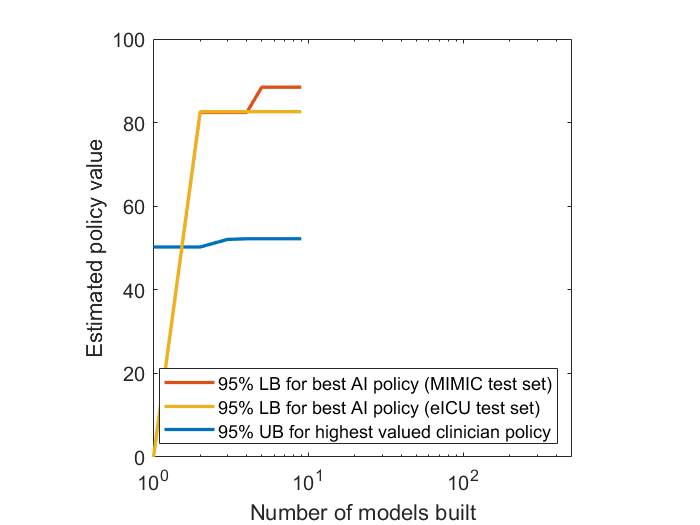

%% FIB 2A plot safety of algos: 95th UB of physicians policy value vs 95th LB of AI policy
% during bulding of 500 different models
% show that the value of AI policy is always guaranteed to be better than doctors' according to the model

clear h
r=recqvi;   %MAKE SURE RECQVI IS SORTED BY MODEL NUMBER!!!

m=zeros(size(r,1),1);
for i=1:size(r,1)
    if r(i,19)>max(m)  %physicians    // OR 19 = 95th percentile!!!!!!!!!!!!
    m(i)=r(i,19);
    else
    m(i)=max(m);
    end
end
figure
h(1)=semilogx(m,'linewidth',2);
hold on

m=zeros(size(r,1),1);
for i=1:size(r,1)
    if r(i,24)>max(m)  %learnt policy
    m(i)=r(i,24);
    else
    m(i)=max(m);
    end
end
h(2)=semilogx(m,'linewidth',2);


m=zeros(size(r,1),1);
for i=1:size(r,1)
    if r(i,14)>max(m)  %learnt policy
    m(i)=r(i,14);
    else
    m(i)=max(m);
    end
end
h(3)=semilogx(m,'linewidth',2);

axis([0 500 0 100])
xlabel('Number of models built')
ylabel('Estimated policy value')
legend([h(2) h(3) h(1)],{'95% LB for best AI policy (MIMIC test set)','95% LB for best AI policy (eICU test set)','95% UB for highest valued clinician policy'},'location','se')
set(gca,'FontSize',12)
axis square
hold off

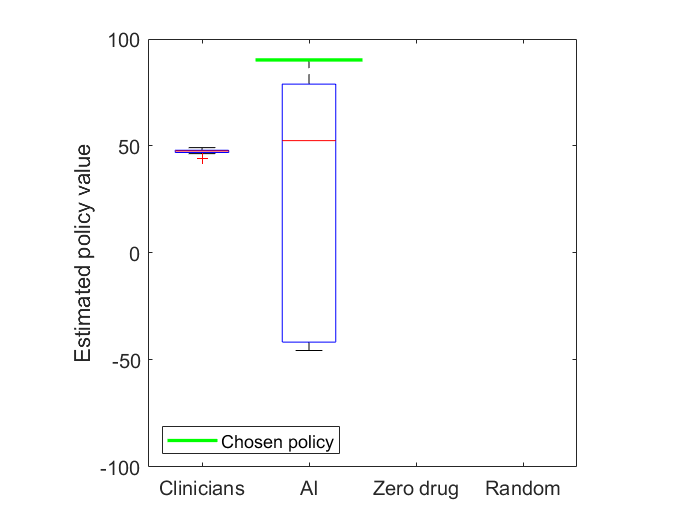



%% FIG 2B BOXPLOT OF POLICY VALUE OVER 500 MODELS -  MIMIC TEST SET ONLY

figure
clear h
boxplot(recqvi(:,[20 22 25 26]),{'Clinicians','AI','Zero drug','Random'}); % some evaluations not done here
h=line([1.5 2.5],[max(recqvi(:,22))  max(recqvi(:,22))] ,'LineWidth',2,'color','g');
axis square
axis([0.5 4.5 -100 100])
legend(h,'Chosen policy','location','sw')
ylabel('Estimated policy value')
set(gca,'FontSize',12)



%% FIG 2C = MODEL CALIBRATION

% TD learning of physicians / bootstrapped, in MIMIC train set.
% This version also records action return and mortality, for the plot (nb: no parfor here)

disp('####   MODEL CALIBRATION - CLINICIANS POLICY EVALUATION WITH TD LEARNING   ####')

####   MODEL CALIBRATION - CLINICIANS POLICY EVALUATION WITH TD LEARNING   ####


tic
[bootql,prog]=offpolicy_eval_tdlearning_with_morta( qldata3train, physpol, ptid,  idx, actionbloctrain, Y90, 0.99, 100 ); %100 reps

Progress:

....................................................................................................
||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||


toc

Elapsed time is 1399.701276 seconds.



nbins=100;
a=prog(:,1);  %Q values of actual actions
qv=floor((a+100)/(200/nbins))+1;  % converts Q values to integers btw 0 and nbins
 m=prog(:,2);  %outcome
h=zeros(nbins,5);  %avg mortality and other results, per bin
 
for i=1:nbins
    
    ii=qv==i;
    h(i,1)=nanmean(m(ii));  %mean mortality in this bin
    if numel(m(ii))>0
     h(i,5)=nanmean(a(ii));  %record the mean of Q values in the bin (to make sure it matches what I expect)
    end
    h(i,2)=std(m(ii))/sqrt(numel(m(ii)));  %SEM of mortality in this bin
    h(i,3)=numel(m(ii));  %nb of data points in this bin
end
 
h(:,4)=h(:,1).*h(:,3)./numel(qv);%weighted average!!
[nansum(h(:,4)) mean(prog(:,2))] %check that both are close!

ans =     0.2493    0.2493


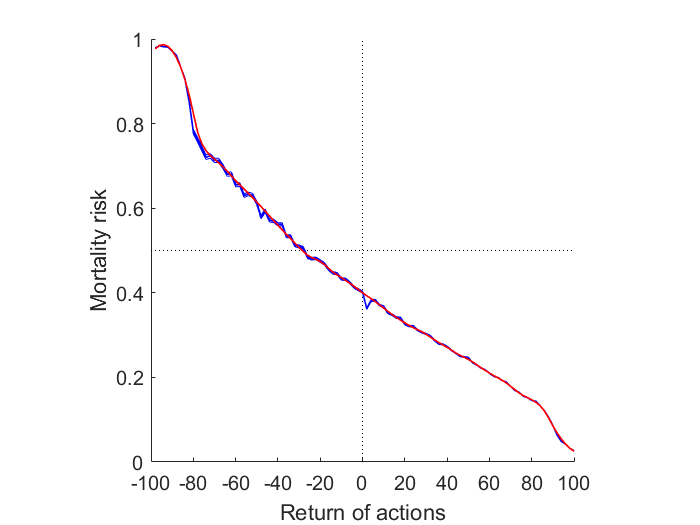

 
yy1=smooth(1:nbins,h(:,1),0.1,'rloess');
figure
hold on
line([0 nbins], [0.5 0.5], 'LineStyle',':','color','k');
line([nbins/2 nbins/2], [0 1], 'LineStyle',':','color','k');
 
H=plot(h(:,1),'b','linewidth',1);
plot(h(:,1)+h(:,2),'b','linewidth',0.5);
plot(h(:,1)-h(:,2),'b','linewidth',0.5);
 
ylabel('Mortality risk');
xlabel('Return of actions')
axis([0 nbins 0 1]); ax=gca;
ax.XTick=0:nbins/10:nbins; ax.XTickLabel =num2cell(-100:20:100);
bw=0.5*200/nbins;
H=plot(yy1,'r','linewidth',1);
axis square
set(gca,'FontSize',12)
hold off

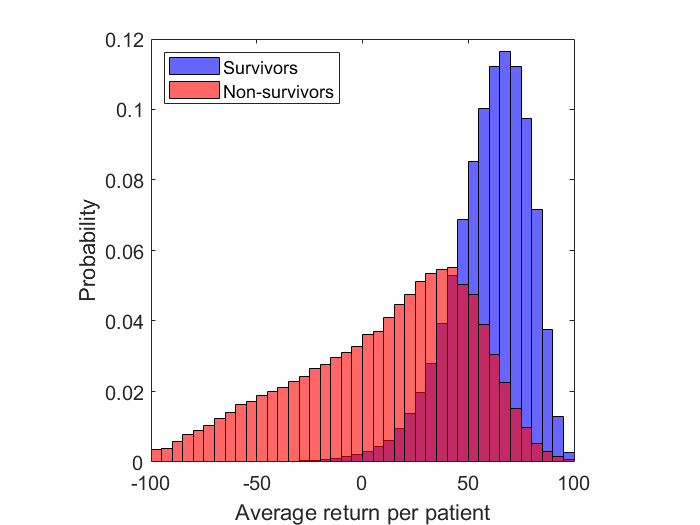



%% FIG 2D = Computes avg Q value per patient / MIMIC TRAIN SET
  
r=array2table(prog);
r.Properties.VariableNames = {'Qoff','morta','id','rep'};
d=grpstats(r,{'rep','id'},{'mean','median','sum'});
edges=-100:5:100;

figure
h(1)=histogram(d.mean_Qoff(d.mean_morta==0),edges,'facecolor','b','normalization','probability');
hold on
h(2)=histogram(d.mean_Qoff(d.mean_morta==1),edges,'facecolor','r','normalization','probability');
hold off
legend([h(1) h(2)],{'Survivors','Non-survivors'},'location','nw')
axis square
xlabel('Average return per patient')
ylabel('Probability')
set(gca,'FontSize',12)



%% evaluation of chosen model on eICU

disp('####   TESTING CHOSEN MODEL ON eICU    ####')

####   TESTING CHOSEN MODEL ON eICU    ####




tic 
 [ booteicuql,booteicuwis] = offpolicy_multiple_eval_010518( qldata2,physpol, 0.99,1,500,8000);

Progress of Q-Learning:

....................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................
||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||

toc

Elapsed time is 4555.828806 seconds.


  
booteicuql=repmat(booteicuql,floor(size(booteicuwis,1)/size(booteicuql,1)),1);  % copy-paste the array, variance is low anyway

[quantile(booteicuql(:,1),0.25)  quantile(booteicuql(:,1),0.5)   quantile(booteicuql(:,1),0.75)]

ans =    44.6316   45.9821   47.3693


[quantile(booteicuwis(:,1),0.25)  quantile(booteicuwis(:,1),0.5)   quantile(booteicuwis(:,1),0.75)]

ans =    84.6034   84.7346   84.7359


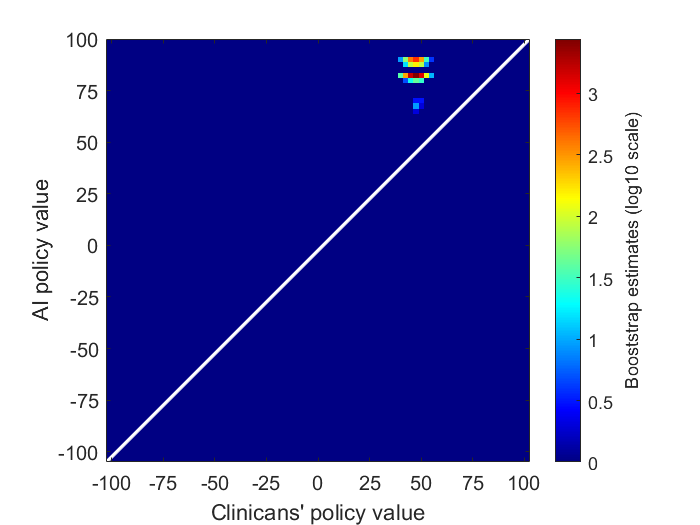

%% FIG 3A - Heatmap of Q values
 
a=[booteicuql booteicuwis];
[counts] = hist3(a,'Edges',{-105:2.5:100 -105:2.5:100}');
 
counts = rot90(counts);
figure
imagesc(log10(counts))
colormap jet
c=colorbar;
c.Label.String = 'Booststrap estimates (log10 scale)';
axis square
hold on
axis([1 83 1 83])
line([1 83],[83 1],'LineWidth',2,'color','w');
ax = gca;
ax.YTick=1:10:100;
ax.YTickLabel = {'100', '75','50','25','0','-25','-50','-75','-100'};
ax.XTick=2:10:100;
ax.XTickLabel = {'-100','-75','-50','-25','0','25','50','75','100'};
xlabel('Clinicans'' policy value')
ylabel('AI policy value')
set(gca,'FontSize',12)
hold off



%%  FIGS 3B3C : 5x5 3D histogram for distrib of action from eICU   

nra=5;
iol=find(ismember(MIMICtable.Properties.VariableNames,{'input_4hourly'}));
vcl=find(ismember(MIMICtable.Properties.VariableNames,{'max_dose_vaso'}));
 
 a= reformat5(:,iol);                   %IV fluid
 a= tiedrank(a(a>0)) / length(a(a>0));   % excludes zero fluid (will be action 1)
 
        iof=floor((a+0.2499999999)*4);  %converts iv volume in 4 actions
        a= reformat5(:,iol); a=find(a>0);  %location of non-zero fluid in big matrix
        io=ones(size(reformat5,1),1);  %array of ones, by default     
        io(a)=iof+1;   %where more than zero fluid given: save actual action
        vc=reformat5(:,vcl);  vcr= tiedrank(vc(vc~=0)) / numel(vc(vc~=0)); vcr=floor((vcr+0.249999999999)*4);  %converts to 4 bins
        vcr(vcr==0)=1; vc(vc~=0)=vcr+1; vc(vc==0)=1;
        ma1=[ median(reformat5(io==1,iol))  median(reformat5(io==2,iol))  median(reformat5(io==3,iol))  median(reformat5(io==4,iol))  median(reformat5(io==5,iol))];  %median dose of drug in all bins
        ma2=[ median(reformat5(vc==1,vcl))  median(reformat5(vc==2,vcl))  median(reformat5(vc==3,vcl))  median(reformat5(vc==4,vcl))  median(reformat5(vc==5,vcl))] ;
  
med=[io vc];
[uniqueValues,~,actionbloc] = unique(array2table(med),'rows');
actionbloctrain=actionbloc(train);
uniqueValuesdose=[ ma2(uniqueValues.med2)' ma1(uniqueValues.med1)'];  % median dose of each bin for all 25 actions
 
iol=find(ismember(MIMICtable.Properties.VariableNames,{'input_4hourly'}));
vcl=find(ismember(MIMICtable.Properties.VariableNames,{'max_dose_vaso'}));
 ma1=[ max(reformat5(io==1,iol))  max(reformat5(io==2,iol))  max(reformat5(io==3,iol))  max(reformat5(io==4,iol))  max(reformat5(io==5,iol))];  %upper dose of drug in all bins
 ma2=[ max(reformat5(vc==1,vcl))  max(reformat5(vc==2,vcl))  max(reformat5(vc==3,vcl))  max(reformat5(vc==4,vcl))  max(reformat5(vc==5,vcl))] ;
 

% define actionbloctest = which actions are taken in the test set ????
vct=eICUraw(:,4); vct(vct>ma2(nra-1))=nra; vct(vct==0)=1; for z=2:nra-1; vct(vct>ma2(z-1) & vct<=ma2(z))=z;end
iot=eICUraw(:,45); for z=2:nra-1; iot(iot>ma1(z-1) & iot<=ma1(z))=z; end;iot(iot>ma1(nra-1))=nra;iot(iot==0)=1;
 
med=[iot vct];

 
figure
subplot(1,2,1)   % /////////////   ACTUAL ACTIONS   ////////////////
 
[counts] = hist3(med,'Edges',{1:5 1:5})./size(med,1);
 counts = flipud(counts);
b=bar3(counts);
for k = 1:length(b)
    zdata = b(k).ZData;
    b(k).CData = zdata;
    b(k).FaceColor = 'interp';
end

ax = gca;
ax.YTick=1:5;
ax.XTick=1:5;
ax.YTickLabel = {'>530', '180-530','50-180','1-50','0'};
ax.XTickLabel = {'0', '0.001-0.08','0.08-0.22','0.22-0.45','>0.45'};
view(45,35)
xlabel('Vasopressor dose')
ylabel('     IV fluids dose')
set(get(gca,'YLabel'),'Position',[6, 6, 0]);
set(get(gca,'XLabel'),'Position',[6, 6, 0]);

title('Clinicians'' policy')
c=colorbar;
c.Label.String = '%';
axis square
axis([0.5 5.5 0.5 5.5 0 0.3])
set(gca,'FontSize',12)
  

disp('##########   Clinician   ##########')

##########   Clinician   ##########


disp('  on vaso     Â¦ on low fluid')

  on vaso     Â¦ on low fluid


disp([sum(sum(counts(:,2:5))) sum(sum(counts(4:5,:)))])

    0.1539    0.4561



disp('  on vaso and low fluids    Â¦ on no vaso and high fluid')

  on vaso and low fluids    Â¦ on no vaso and high fluid


disp([sum(sum(counts(3:5,2:5)))  sum(sum(counts(1:2,1)))])

    0.0614    0.2676



disp('  on low vaso ')

  on low vaso 


disp([sum(sum(counts(:,2:4)))  ])

    0.1163





subplot(1,2,2)  % /////////////   OPTIMAL ACTIONS   ////////////////
OA1=OptimalAction(idxtest2);%test);              %optimal action for each record
a=[OA1 floor((OA1-0.0001)./5)+1 OA1-floor(OA1./5)*5];
a(a(:,3)==0,3)=5;
med=a(:,[2 3]);
[counts] = hist3(med,'Edges',{1:5 1:5})./size(med,1);
  counts = flipud(counts);
 
 b=bar3(counts);
for k = 1:length(b)
    zdata = b(k).ZData;
    b(k).CData = zdata;
    b(k).FaceColor = 'interp';
end

disp('##########   AI Clinician   ##########')

##########   AI Clinician   ##########


disp('  on vaso     Â¦ on low fluid')

  on vaso     Â¦ on low fluid


disp([sum(sum(counts(:,2:5))) sum(sum(counts(4:5,:)))])

    0.4503    0.3824



disp('  on vaso and low fluids    Â¦ on no vaso and high fluid')

  on vaso and low fluids    Â¦ on no vaso and high fluid


disp([sum(sum(counts(3:5,2:5)))  sum(sum(counts(1:2,1)))])

    0.2340    0.2220



disp('  on low vaso ')

  on low vaso 


disp([sum(sum(counts(:,2:4)))  ])

    0.3935



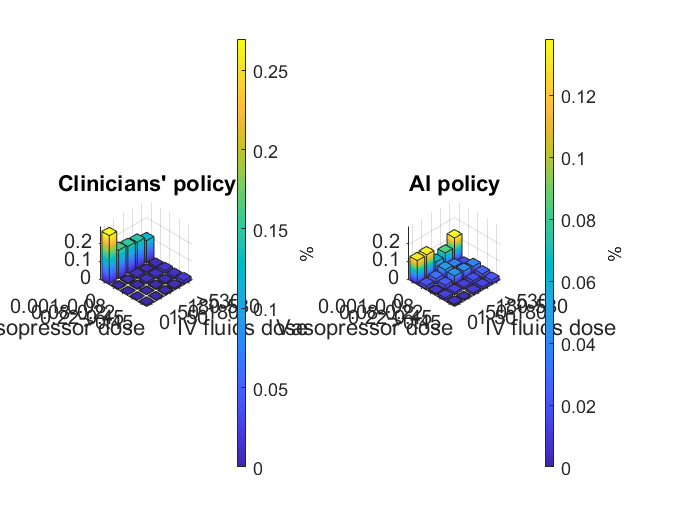



colorbar
ax = gca;
ax.YTick=1:5;
ax.XTick=1:5;
ax.YTickLabel = {'>530', '180-530','50-180','1-50','0'};
ax.XTickLabel = {'0', '0.001-0.08','0.08-0.22','0.22-0.45','>0.45'};
view(45,35)
xlabel('Vasopressor dose')
ylabel('     IV fluids dose')
set(get(gca,'YLabel'),'Position',[6, 6, 0]);
set(get(gca,'XLabel'),'Position',[6, 6, 0]);
title('AI policy')
c=colorbar;
c.Label.String = '%';
axis square
axis([0.5 5.5 0.5 5.5 0 0.3])
set(gca,'FontSize',12)



%% FIGS 3D & 3E : "Ucurves" eICU TEST SET with bootstrapped CI

t=[-1250:100:1250]; t2=[-1.05:0.1:1.05];

nr_reps=200; 
p=unique(qldata2(:,8));
prop=10000/numel(p); %10k patients of the samples are used
prop=min([prop 0.75]);  %max possible value is 0.75 (75% of the samples are used)

% ACTUAL DATA
disp('U-curves with actual doses...')

U-curves with actual doses...


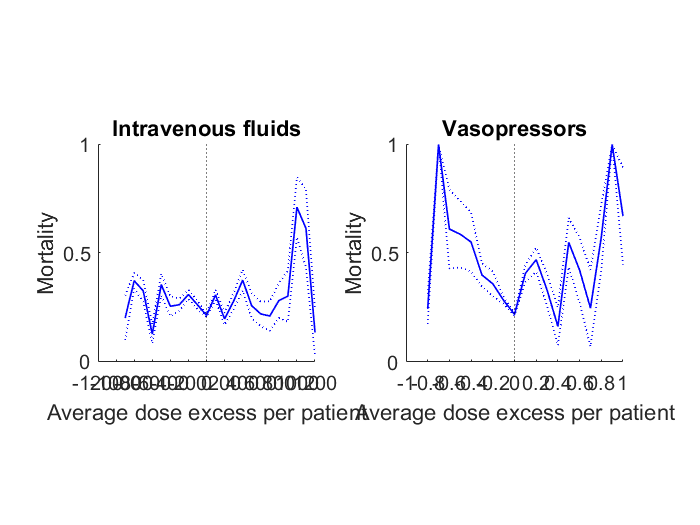

% column key:  9 given fluid    10 given vaso    11 model dose fluid     12 model dose vaso
qldata=qldata2(qldata2(:,3)~=0,:);
qldata(:,14)=qldata(:,10)-qldata(:,12);
qldata(:,15)=qldata(:,9)-qldata(:,11);

r=array2table(qldata(:,[8 13 14 15]));  
r.Properties.VariableNames = {'id','morta','vaso','ivf'};
d=grpstats(r,'id',{'mean','median','sum'});
d3=([d.mean_morta d.mean_vaso d.mean_ivf d.median_vaso d.median_ivf d.sum_ivf d.GroupCount]);
r1=zeros(numel(t)-1,nr_reps,2);
r2=zeros(numel(t2)-1,nr_reps,2);

for rep=1:nr_reps
    
%     disp(rep);
    ii=floor(rand(size(p,1),1)+prop);     % select a random sample of trajectories
    d4=d3(ii==1,:);
    
    a=[];     % IVF
    b=[];     % vasopressors
    
    
    for i=1:numel(t)-1
        ii=d4(:,5)>=t(i) & d4(:,5)<=t(i+1);  %median
        a=[a ; [t(i) t(i+1) sum(ii) nanmean(d4(ii,1)) nanstd(d4(ii,1))]];
    end
    
    r1(:,rep,1)=a(:,4);
    r1(:,rep,2)=a(:,3);
    r1(:,rep,3)=a(:,5)./sqrt(a(:,3));  % SEM !!
    
    for i=1:numel(t2)-1
        ii=d4(:,4)>=t2(i) & d4(:,4)<=t2(i+1);   %median
        b=[b ; [t2(i) t2(i+1) sum(ii) nanmean(d4(ii,1)) nanstd(d4(ii,1))]];
    end
    
    r2(:,rep,1)=b(:,4);
    r2(:,rep,2)=b(:,3);
    r2(:,rep,3)=b(:,5)./sqrt(b(:,3));  % SEM !!

end

a1=nanmean(r1(:,:,1),2);
a2=nanmean(r2(:,:,1),2);


% computing SEM in each bin
s1=nan(numel(t)-1,1);
for i=1:numel(t)-1
s1(i)=nanstd([ones(nansum(r1(i,:,1).*r1(i,:,2) ),1); zeros(nansum((1-r1(i,:,1)).*r1(i,:,2)),1)])/sqrt(nansum(r1(i,:,2)));
end
s2=nan(numel(t2)-1,1);
for i=1:numel(t2)-1
s2(i)=nanstd([ones(nansum(r2(i,:,1).*r2(i,:,2) ),1); zeros(nansum((1-r2(i,:,1)).*r2(i,:,2)),1)])/sqrt(nansum(r2(i,:,2)));
end





%% FIG 3D & 3E - "U-CURVE"  PLOT  ONLY OPTIMAL POLICY   
t=[-1250:100:1250]; t2=[-1.05:0.1:1.05];

s=0;  %  !!!!  SMOOTHING FACTOR  !!!! use 0 for no smooth curves
f=10;   %inflation factor for SEM (for visualisation purposes)
figure
if s>0
    
yy1=smooth(1:numel(a1),a1,s,'loess');
yy2=smooth(1:numel(ar1),ar1,s,'loess');
end
subplot(1,2,1)
hold on
h=plot(a1,'b','linewidth',1);
plot(a1+f*s1,'b:','linewidth',1)
plot(a1-f*s1,'b:','linewidth',1)

plot([numel(a1)/2+.5 numel(a1)/2+.5],[0 1],'k:');
xlabel('Average dose excess per patient')
ylabel('Mortality')
axis([1 numel(a1) 0 1]); ax=gca;
t=t-(t(end)-t(end-1))/2;
t=round(t,2);
t=t(2:2:end);
ax.XTick=1:2:2*numel(t);
ax.XTickLabel =num2cell(t); 
% rotateXLabels( gca, 90)
if s>0
plot(yy1,'b','linewidth',2);
plot(yy2,'r','linewidth',2);
end
axis square
title('Intravenous fluids')
set(gca,'FontSize',12)

hold off

subplot(1,2,2)
if s>0
yy1=smooth(1:numel(a2),a2,s,'loess');
yy2=smooth(1:numel(ar2),ar2,s,'loess');
end

hold on
h=plot(a2,'b','linewidth',1);
plot(a2+f*s2,'b:','linewidth',1)
plot(a2-f*s2,'b:','linewidth',1)
plot([numel(a2)/2+.5 numel(a2)/2+.5],[0 1],'k:');

xlabel('Average dose excess per patient')
ylabel('Mortality')
axis([1 numel(a2) 0 1]); ax=gca;
t2=t2-(t2(end)-t2(end-1))/2;
t2=round(t2,2);
t2=t2(2:2:end);
ax.XTick=1:2:2*numel(t2);
ax.XTickLabel =num2cell(t2); 
% rotateXLabels( gca, 90)

if s>0
    plot(yy1,'b','linewidth',2);
    plot(yy2,'r','linewidth',2);
end

axis square
title('Vasopressors')
set(gca,'FontSize',12)
hold off

%% FIG SA - FEATURE IMPORTANCE for VASOPRESSORS, with bootstraping

nn=100;  %nr bootstraps
fi=zeros(46,nn);
fi2=zeros(46,nn);
colbin = {'gender','mechvent','max_dose_vaso','re_admission'};  %will simply substract 0.5 to center around 0
colnorm={'age','Weight_kg','GCS','HR','SysBP','MeanBP','DiaBP','RR','Temp_C','FiO2_1', 'Potassium','Sodium','Chloride','Glucose','Magnesium','Calcium','Hb','WBC_count','Platelets_count','PTT','PT','Arterial_pH','paO2','paCO2', 'Arterial_BE','HCO3','Arterial_lactate','SOFA','SIRS','Shock_Index','PaO2_FiO2','cumulated_balance'};
collog={'SpO2','BUN','Creatinine','SGOT','SGPT','Total_bili','INR','input_total','input_4hourly','output_total','output_4hourly'};
v=MIMICtable(1,[colbin colnorm collog]).Properties.VariableNames; %get he right column names!

% REMOVE COL 4 = VASOPRESSORS
v2=v([1:3 5:47]);  %this is the list of (correct) feature names
v2=regexprep(v2,'_',' ');v2=regexprep(v2,' tev','');v2=regexprep(v2,'bp',' BP');

tic;
for i=1:nn
%      i
    grp=floor(100*rand(size(eICUraw,1)-1,1)+1)<=5;  %selects a random x% of data for training
    
    %actual policy
    br=TreeBagger(15,eICUraw(grp,[1:3 5:47]),qldata(grp,10)>0,'method','c','maxnumsplits',30,'MinLeafSize',500,'OOBVarImp','on','OOBPred','Off','MinLeaf',150,'PredictorNames',v2);
    fi(:,i)=br.OOBPermutedPredictorDeltaError;
    %optimal policy
    br2=TreeBagger(15,eICUraw(grp,[1:3 5:47]),qldata(grp,12)>0,'method','c','maxnumsplits',30,'MinLeafSize',500,'OOBVarImp','on','OOBPred','Off','MinLeaf',150,'PredictorNames',v2);
    
    fi2(:,i)=br2.OOBPermutedPredictorDeltaError;

end
toc

Elapsed time is 158.792436 seconds.


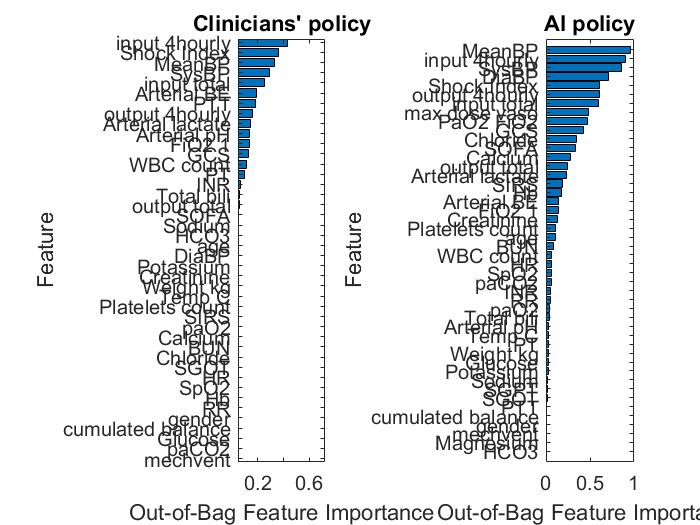



fi=mean(fi,2);  %average over all models
fi2=mean(fi2,2);


figure
subplot(1,2,1)
[~,i]=sort(fi,'asc');
barh(fi(i))
ylabel 'Feature'
xlabel 'Out-of-Bag Feature Importance'
ax=gca;
ax.YTick=1:46;
ax.YTickLabel =v2(i);
title('Clinicians'' policy')
set(gca,'FontSize',12)
subplot(1,2,2)
[~,i]=sort(fi2,'asc');
barh(fi2(i))
ylabel 'Feature'
xlabel 'Out-of-Bag Feature Importance'
ax=gca;
ax.YTick=1:46;
ax.YTickLabel =v2(i);
title('AI policy')
set(gca,'FontSize',12)

%% predict IV fluid O/N

fi=zeros(46,nn);
fi2=zeros(46,nn);
% REMOVE COL 45 = IV Fluids
v2=v([1:44 46:47]);  %this is the list of (correct) feature names
v2=regexprep(v2,'_',' ');v2=regexprep(v2,' tev','');v2=regexprep(v2,'bp',' BP');

tic;
for i=1:nn
    grp=floor(100*rand(size(eICUraw,1)-1,1)+1)<5;  %selects a random x% of data for training
    %actual policy
    br=TreeBagger(10,eICUraw(grp,[1:44 46:47]),qldata(grp,9)>0,'method','c','maxnumsplits',30,'MinLeafSize',500,'OOBVarImp','on','OOBPred','Off','MinLeaf',150,'PredictorNames',v2);%100+floor(200*rand()) );
    fi(:,i)=br.OOBPermutedPredictorDeltaError;
    %optimal policy
    br2=TreeBagger(10,eICUraw(grp,[1:44 46:47]),qldata(grp,11)>0,'method','c','maxnumsplits',30,'MinLeafSize',500,'OOBVarImp','on','OOBPred','Off','MinLeaf',150,'PredictorNames',v2);%100+floor(200*rand()) );
    
    fi2(:,i)=br2.OOBPermutedPredictorDeltaError;
end
toc

Elapsed time is 104.467553 seconds.


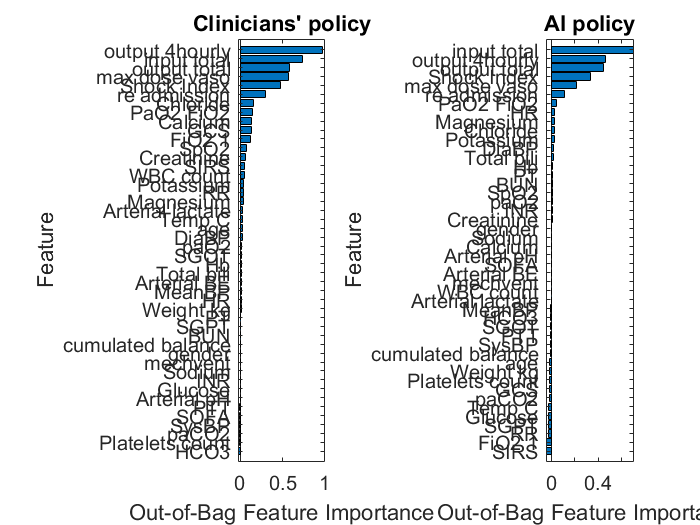


fi=mean(fi,2);
fi2=mean(fi2,2);
figure
subplot(1,2,1)
[~,i]=sort(fi,'asc');
barh(fi(i))
ylabel 'Feature'
xlabel 'Out-of-Bag Feature Importance'
v2=regexprep(v2,'_',' ');
ax=gca;
ax.YTick=1:46;
ax.YTickLabel =v2(i);
title('Clinicians'' policy')
set(gca,'FontSize',12)
subplot(1,2,2)
[~,i]=sort(fi2,'asc');
barh(fi2(i))
ylabel 'Feature'
xlabel 'Out-of-Bag Feature Importance'
v2=regexprep(v2,'_',' ');
ax=gca;
ax.YTick=1:46;
ax.YTickLabel =v2(i);
title('AI policy')
set(gca,'FontSize',12)

%%   #################    NUMERICAL  RESULTS    ##########################

% STATS btw given and reco doses 22/05/17 in EICU

% category 1 = dose excess negative = given less than reco
% category 3 = dose excess positive = given more than reco

% similar dose norad if given is withing +/- 10% of reco or 0.02 mkm or 10 ml/h

% KEY:
%    rectest(:,9)= rectest(:,4)- rectest(:,5);  %given  - reco  VASOPRESSORS
%    rectest(:,10)= rectest(:,6)- rectest(:,7);  %given - reco  FLUIDS

qldata=qldata2(qldata2(:,3)~=0,:);
qldata(:,14)=qldata(:,10)-qldata(:,12);
qldata(:,15)=qldata(:,9)-qldata(:,11);

% VASOPRESSORS
j=abs((qldata(:,10)-qldata(:,12))./(qldata(:,10))).*100;% PCT difference btw given and reco  VASOPRESSORS
qldata(:,17)=abs(qldata(:,14))<=0.02| j<=10;   %close dose
ii=qldata(:,17)==1;   
% sum(ii)/numel(ii)  % how many received close to optimal dose?
qldata(ii,17)=qldata(ii,17)+1;% category 2 = dose similar
ii=qldata(:,17)==0 & qldata(:,14)<0;%less than reco
qldata(ii,17)=1;% category 1
ii=qldata(:,17)==0 & qldata(:,14)>0; %more than reco
qldata(ii,17)=3;% category 3

% stats for all 3 categories
a=[];
for i=1:3
    ii=qldata(:,17)==i;   %rows in qldata who corresp to this category
    j=qldata(ii,14);   %dose

a=[a;    [sum(ii)/numel(ii) mean(qldata(ii,13)) std(qldata(ii,13))./sqrt(sum(ii)) quantile(j,0.25) median(j) quantile(j,0.75)]];
end


% FLUIDS
j= abs((qldata(:,9)-qldata(:,11))./(qldata(:,9))).*100;% PCT difference btw given and reco FLUIDS
qldata(:,18)=j<=10| abs(qldata(:,15))<=40;   %close dose (40 ml/4h = 10 ml / h)
ii=qldata(:,18)==1;   
% sum(ii)/numel(ii) % how many received close to optimal dose?
qldata(ii,18)=qldata(ii,18)+1;   % category 2 = dose similar
ii=qldata(:,18)==0 & qldata(:,15)<0;%less than reco
qldata(ii,18)=1;  %cat 1
ii=qldata(:,18)==0 & qldata(:,15)>0; %more than reco
qldata(ii,18)=3;   % cat 3


% stats for all 3 categories
% a=[];
for i=1:3
    ii=qldata(:,18)==i;   %rows in qldata who corresp to this category
    j=qldata(ii,15)./4;   %dose in ml/h

a=[a;    [sum(ii)/numel(ii) mean(qldata(ii,13)) std(qldata(ii,13))./sqrt(sum(ii)) quantile(j,0.25) median(j) quantile(j,0.75)]];
end

i=a(1,1)/(a(1,1)+a(3,1)); ii=a(6,1)/(a(4,1)+a(6,1));
a=array2table(a);
a=[ array2table({'Vaso: Less than reco', 'Vaso: Similar dose', 'Vaso: More than reco', 'Fluids: Less than reco' ,'Fluids: Similar dose' ,'Fluids: More than reco'}') a];
a.Properties.VariableNames={'category','fraction','avg_mortality','SEM','Q1_dose','Q2_dose','Q3_dose'};

disp(a)

             category             fraction    avg_mortality       SEM       Q1_dose    Q2_dose    Q3_dose
    __________________________    ________    _____________    _________    _______    _______    _______

    {'Vaso: Less than reco'  }     0.37899       0.27576       0.0030726     -0.27     -0.135       -0.04
    {'Vaso: Similar dose'    }      0.5244       0.21996       0.0024211         0          0           0
    {'Vaso: More than reco'  }    0.096611       0.39904       0.0066689      0.09        0.2        0.45
    {'Fluids: Less than reco'}     0.37525       0.27975       0.0031015    -198.5     -89.75     -51.062
    {'Fluids: Similar dose'  }     0.35979        0.2262       0.0029522      -7.5          0           0
    {'Fluids: More 

fprintf(' Among patients who did not receive the recommended dose of vasopressors, fraction of patients who received less than recommended : ');       fprintf('%f \n',i); 

 Among patients who did not receive the recommended dose of vasopressors, fraction of patients who received less than recommended : 0.796866 


fprintf(' Among patients who did not receive the recommended dose of IV fluids, fraction of patients who received more than recommended : ');       fprintf('%f \n',ii);

 Among patients who did not receive the recommended dose of IV fluids, fraction of patients who received more than recommended : 0.413873 




%% #########    dose of drugs in the 5 bins      ###############

iol=find(ismember(MIMICtable.Properties.VariableNames,{'input_4hourly'}));
vcl=find(ismember(MIMICtable.Properties.VariableNames,{'max_dose_vaso'}));

%boundaries + median doses for each action
disp('VASOPRESSORS')

VASOPRESSORS


for i=1:5
[min(reformat5(vc==i,vcl)) median(reformat5(vc==i,vcl)) max(reformat5(vc==i,vcl))]
end

ans =      0     0     0


ans =     0.0020    0.0400    0.0790


ans =     0.0800    0.1350    0.2000


ans =     0.2010    0.2700    0.4490


ans =     0.4500    0.7870  170.8400



disp('IV FLUIDS')

IV FLUIDS


for i=1:5
[min(reformat5(io==i,iol)) median(reformat5(io==i,iol)) max(reformat5(io==i,iol))]
end

ans =      0     0     0


ans =     0.0160   30.0000   48.6750


ans =    48.6800   80.0040  150.0000


ans =   150.0000  290.0000  500.0000


ans = 	1.0e+04 *

    0.0500    0.0874    1.3199


tic
     save('C:\Users\amrut\Projects\AI_Clinician\Amrut_Core_All_Data_120220.mat', '-v7.3');
toc

Elapsed time is 38.835846 seconds.
